clc
clear 
rng(2024)

% 按照设定相位初始化卫星队列
sat_num=19;
for k = 1:sat_num
    sat_index(1,k) = 0 + (k-1)*15; % initial phase index
end
sat_array=gen_satellite_array_by_index(sat_index);


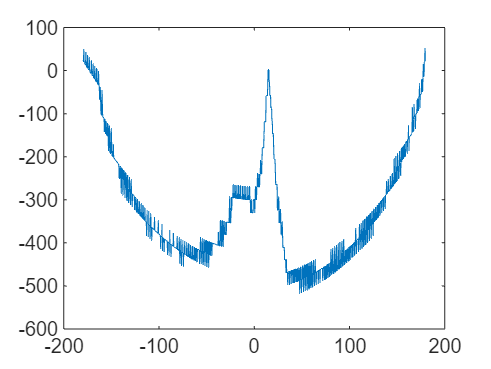


% 重新设定时间分辨率
% h=1;
% days=1;
% for i=1:sat_num
%     sat_array{i}=sat_array{i}.set_time_parameters(days,h);
%     sat_array{i}=sat_array{i}.update();
% end


gama=0.01;
fun=@(x)cal_ob_fun(x,sat_array,1,gama);
x0=0;
varn=1;

x=linspace(-180,180,1000);
for i=1:length(x)
    a(i)=fun(x(i));
end
plot(x,a)

% % fminbnd方法
tic
% options = optimset('Display','iter');
[x,fval] = fminbnd(fun,-180,180)

x = 42.2440

fval = -492.1544

toc

历时 0.148568 秒。



tic

% 求解
[x,fval] = patternsearch(fun,x0,[],[],[],[],repmat(-180,...
    size(x0)),repmat(180,size(x0)));

patternsearch stopped because the mesh size was less than options.MeshTolerance.


toc

历时 0.418538 秒。


x

x = 40.4272

fval

fval = -493.6564